     4     4



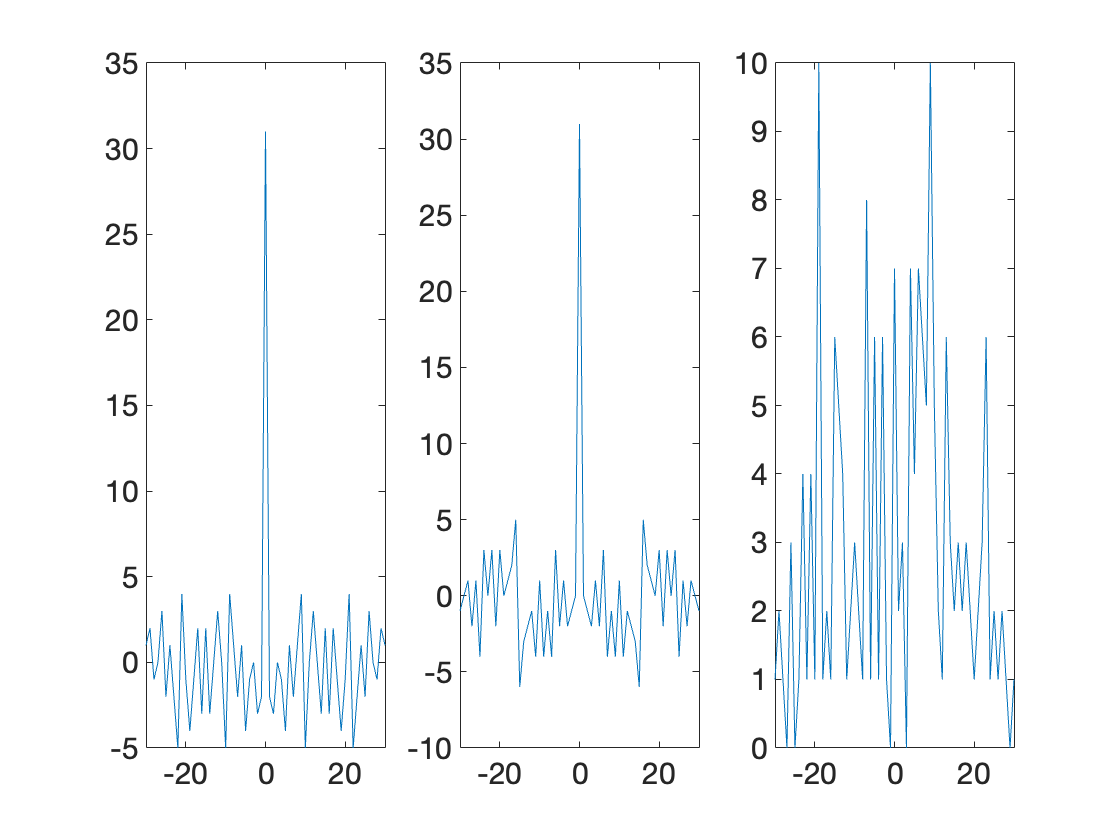

     4     4



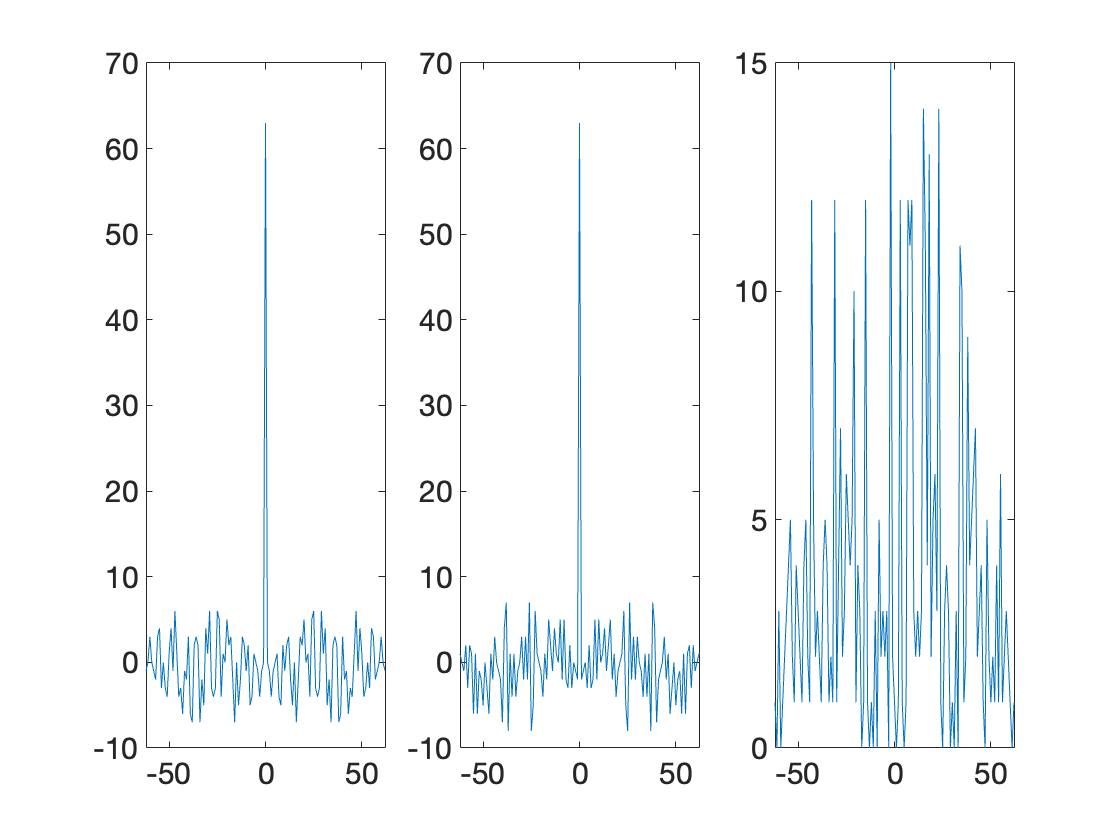

     4     4



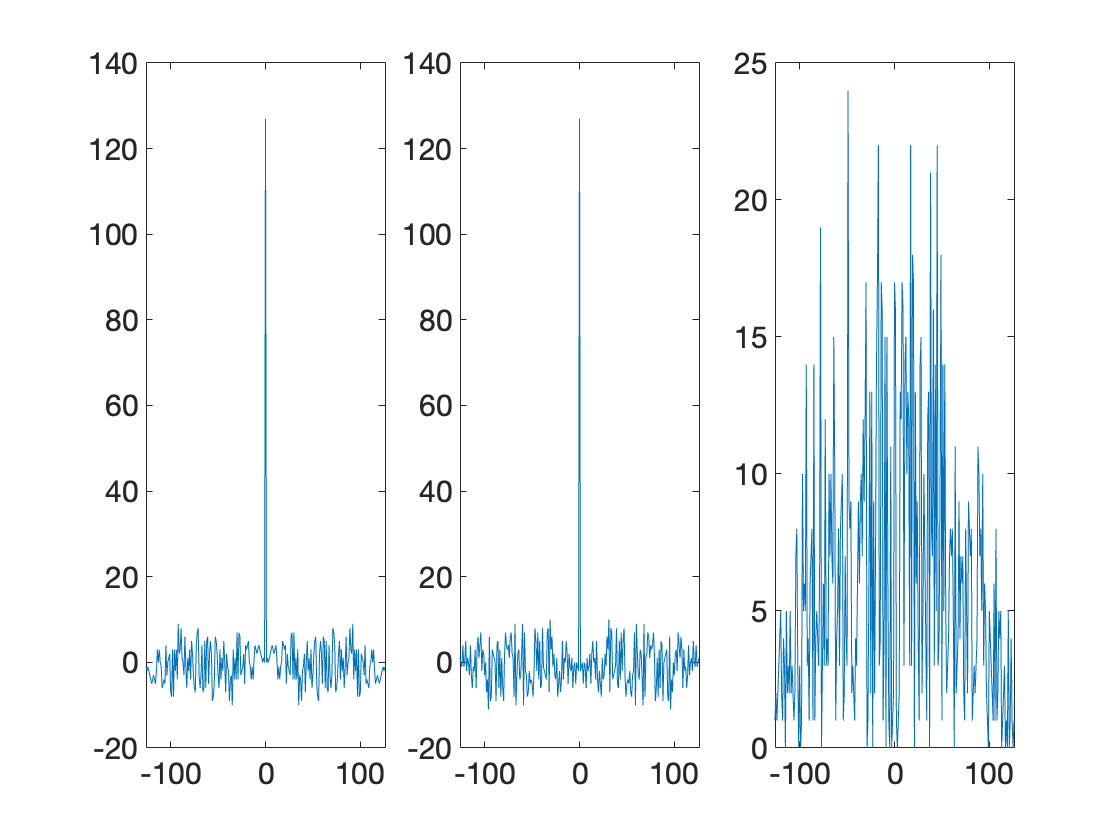

     4     4



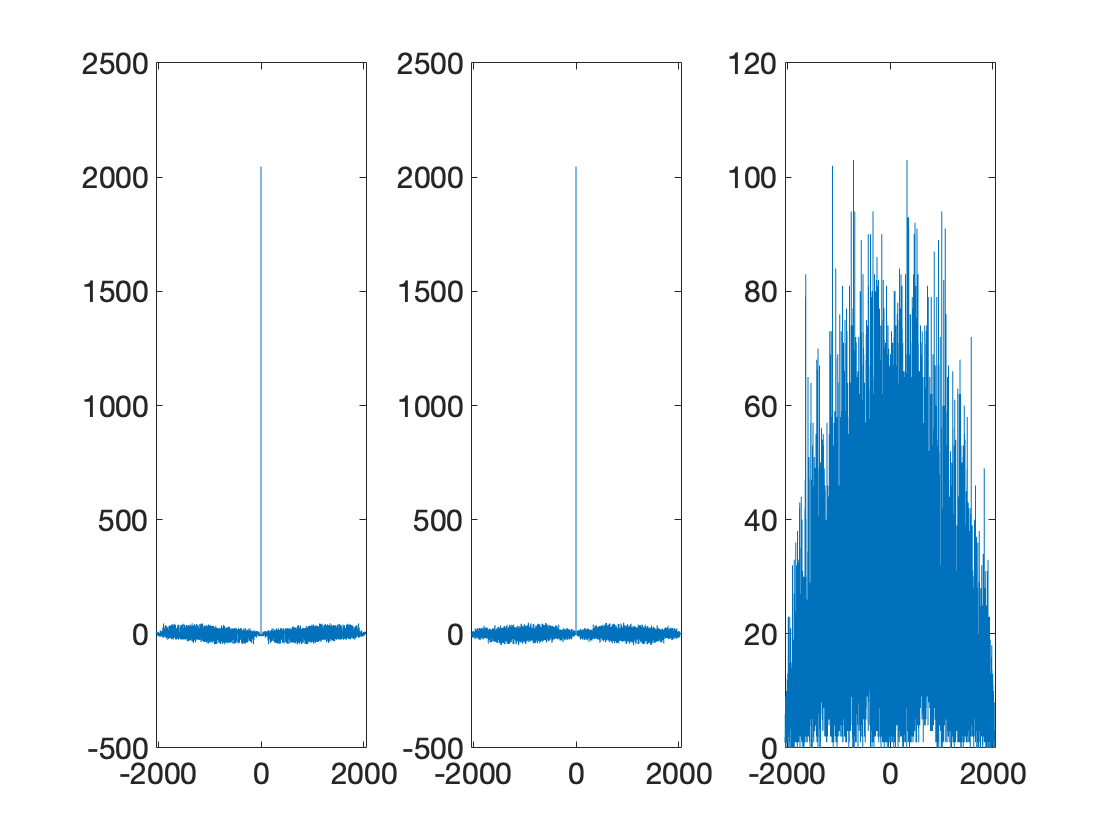

     4     4



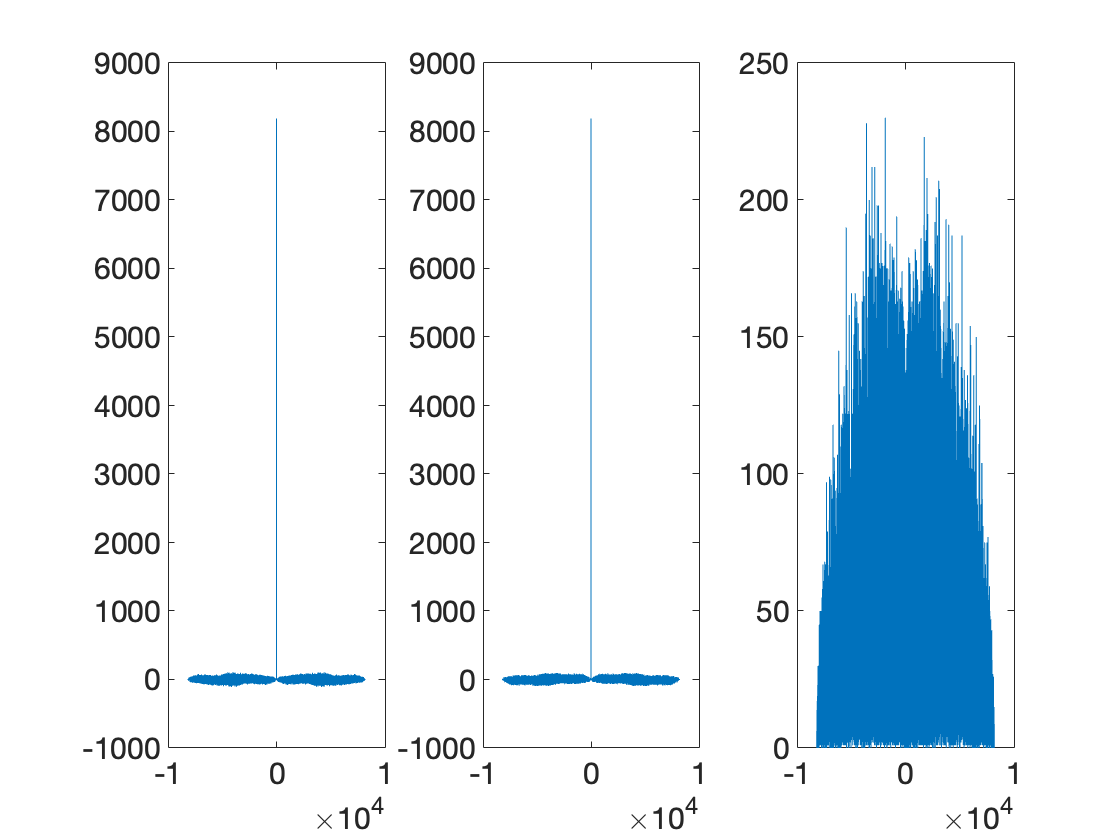

     4     4



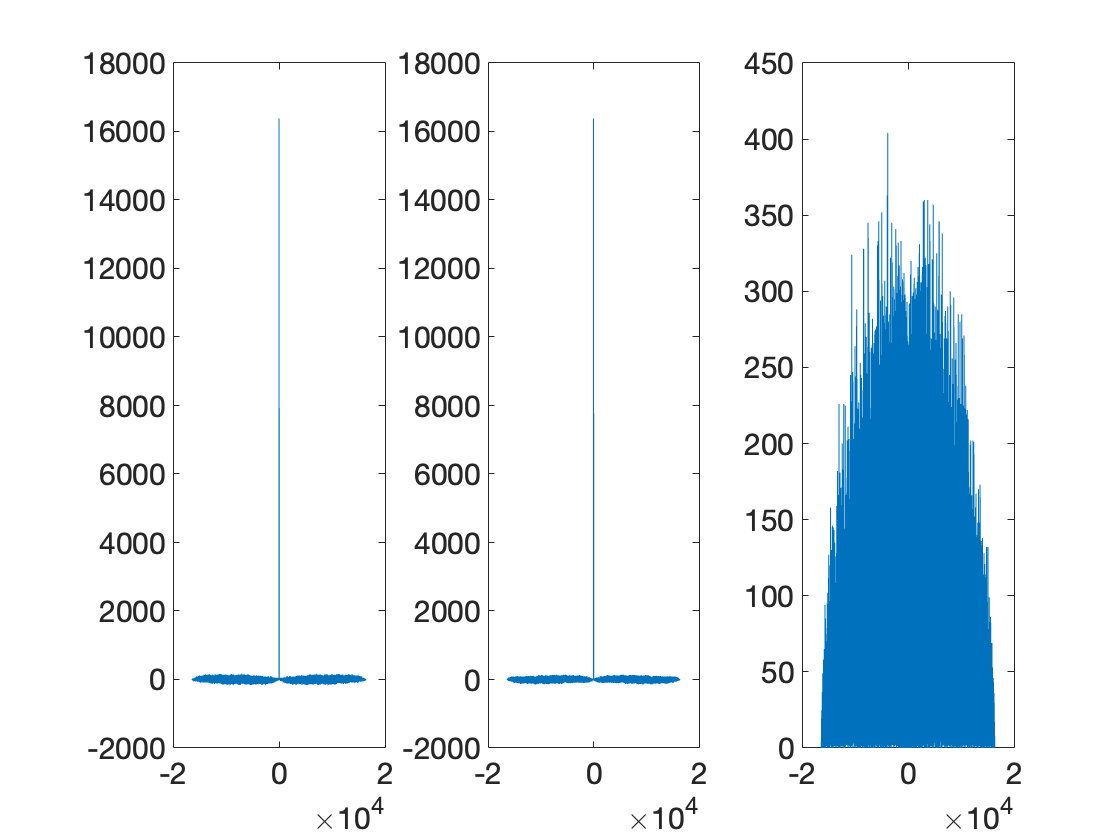

     4     4



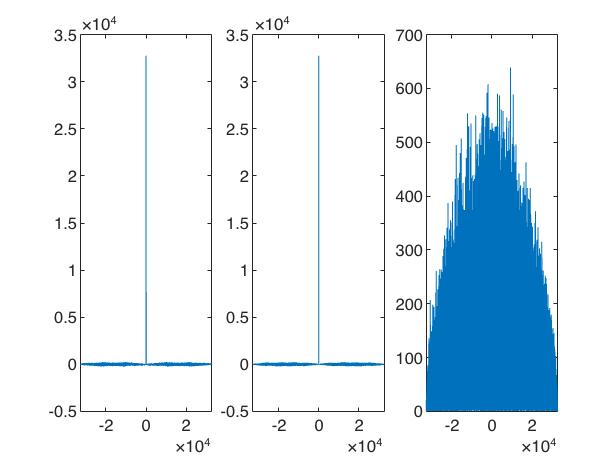

     4     4



     4     4



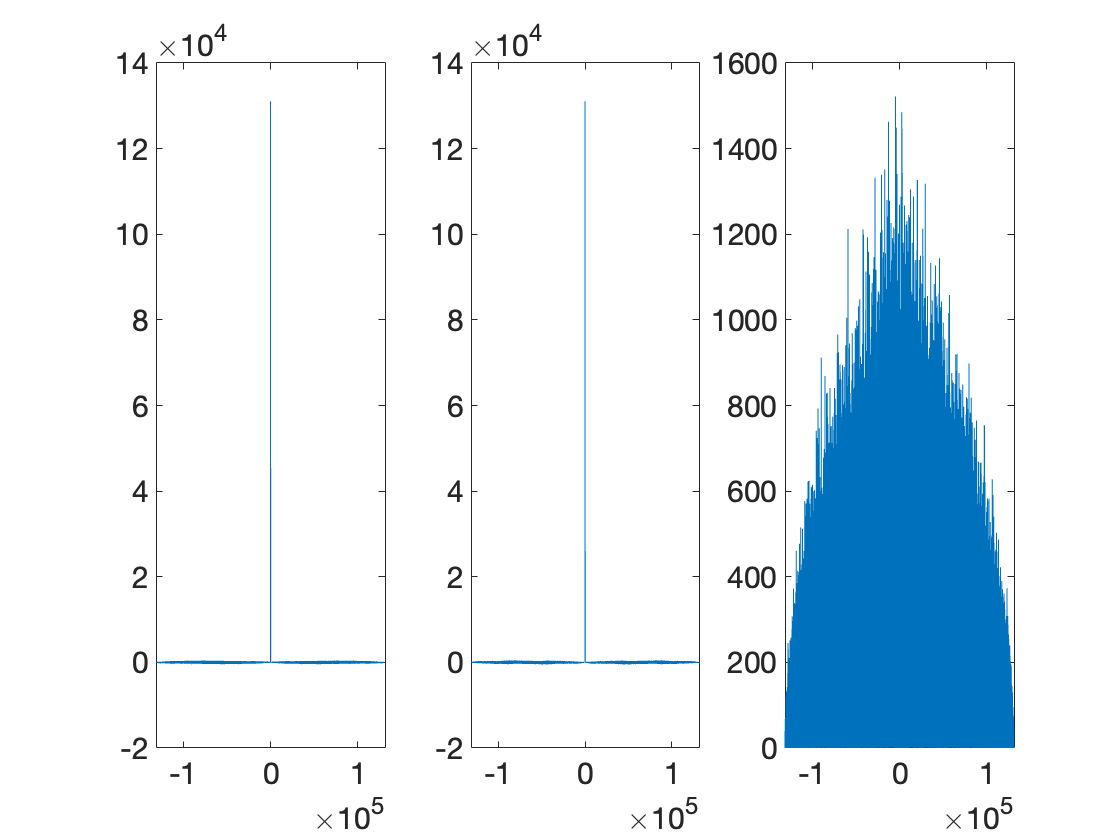

     4     4



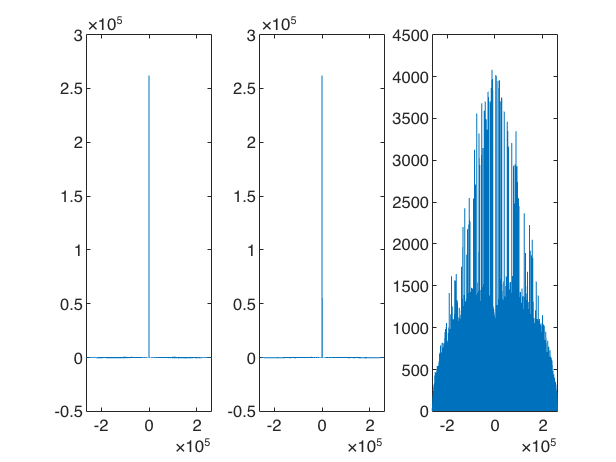



%fs = 1e6; % sampling freq
%T = 25e-3; % length of the sequence (probe signal) in seconds % (20 - 100ms)
%r = 1500; % rate
% filter
%rolloff = 1/8;
%M = r*T;

N = 500;
% best kasami [14 13 8 4 0]
% best lfsr [10 7 0]
% [21 19 0], [22 21 0], [23 18 0], [24 23 22 17 0], [25 22 0], [26 25 24 20 0], [27 26 25 22 0], [28 25 0], [29 27 0], [30 29 28 7 0], [31 28 0], [32 31 30 10 0], [33 20 0], [34 15 14 1 0], [35 2 0], [36 11 0], [37 12 10 2 0], [38 6 5 1 0], [39 8 0], [40 5 4 3 0], [41 3 0], [42 23 22 1 0], [43 6 4 3 0], [44 6 5 2 0], [45 4 3 1 0], [46 21 10 1 0], [47 14 0], [48 28 27 1 0], [49 9 0], [50 4 3 2 0], [51 6 3 1 0], [52 3 0], [53 6 2 1 0]
%lfsr_polys = {[2 1 0], [4 3 0], [6 5 0], [7 3 0], [8 6 5 4 0], [10 7 0], [12 11 8 6 0], [14 13 8 4 0],[16 15 13 4 0], [18 11 0], [19 18 17 14 0], [20 17 0]};
%kasami_polys = {[4 1 0], [6 1 0], [8 4 3 2 0], [10 3 0], [12 6 4 1 0]} ;
%gold_fpolys = {[5 2 0], [6 1 0], [7 3 0], [9 4 0], [10 3 0], [11 2 0], [13 4 3 1 0]};
%gold_spolys = {[5 4 3 2 0], [6 5 2 1 0], [7 3 2 1 0], [9 6 4 3 0], [10 8 3 2 0], [11 8 5 2 0], [13 12 10 9 7 6 5 1 0]};


mseq_poly = [
    5 45 73; 
    6 133 163; 
    7 271 367; 
    11 4005 4445; 
    13 20033 24623;
    14 42103 43333;
    15 102043 110013;
    16 210013 234313;
    17 400431 525251;
    18 1002241 1115701;
    19 2020471 2013211;
    %20 4001051 4004515;
    %21 10040205 10020045;
    %22 20001043 25200127;
    %23 40404041 40010061;
    %24 125245661 113763063;
    %25 204000051 201014171;
    ];

kasami_poly = [
    6 103 147 155 141; 
    8 435 551 747 453;
    11 4005 6015 7413 7335; 
    14 42103 43333 51761 40503;
    16 210013 234313 233303 307107;
    18 1002241 1115701 1703601 1025711;
    ];

gold_poly = [
    5 45 75 67 51; 
    6 103 147 155 141; 
    7 211 217 277 203; 
    8 435 551 747 453;
    9 1021 1461 1423 1055;
    11 4005 6015 7413 7335; 
    13 20033 23261 30171 34723;
    14 42103 43333 51761 40503;
    15 102043 110013 102067 104307;
    16 210013 234313 233303 307107;
    17 400431 525251 410117 400731;
    18 1002241 1115701 1703601 1025711;
    19 2020471 2013211 2570103 2561427;
    20 4001051 4004515 6000031 4442235;
    21 10040205 10020045 10040315 10103075;
    22 20001043 25200127 20401207 20430607;
    23 40404041 40010061 50000241 40220151;
    25 204000051 201014171 200402017 204204057;
    %26 430216473 402365755 426225667 510664323;
    %27 1001007071 1020024171 1102210617 1112225171;
    %28 2104210431 2002502115 2020006031 2001601071;
    %29 4004004005 4002200115 4004064275 4010000045;
    %30 10104264207 10115131333 10040000007 11326212703;
    %31 21042107357 20060140231 20000200435 20202040217;
    %32 40460216667 40035532523 42003247143 41760427607;
    %33 100601431001 100502430041 104020466001 111100021111;
    %34 211636220473 227712240037 377000007527 201472024107;
    ];


codeMethod = "lfsr";
ccnoise_list = {};
psr_list = {};
ccoef_list = {};
acr_list = {};
degs = [];



r = [4, 4];

for i = 1:(size(mseq_poly) - 1)

    %r = randperm([1 (2^max(cell2mat(lfsr_polys(i))) - 1)], 1, 2);
    %r = randperm(2^max(cell2mat(mseq_poly(i))) - 1, 2);
    
    if codeMethod == "kasami"
        r = 2*r - 1;
    end
    disp(r);
    
    if codeMethod == "lfsr"
        anchor1 = genBasebandSig(r(1), mseq_poly(i, 1), codeMethod, oct2poly(mseq_poly(i, 2)));    
        anchor2 = genBasebandSig(r(2), mseq_poly(i, 1), codeMethod, oct2poly(mseq_poly(i, 3)));
    
    elseif codeMethod == "kasami"
        anchor1 = genBasebandSig(r(1), mseq_poly(i, 1), codeMethod, oct2poly(kasami_poly(i, 2)));    
        anchor2 = genBasebandSig(r(2), mseq_poly(i, 1), codeMethod, oct2poly(kasami_poly(i, 3)));

    elseif codeMethod == "gold"
        gold_poly(i, 2)
        gold_poly(i, 3)
        gold_poly(i, 4)
        gold_poly(i, 5)
        anchor1 = genBasebandSig(r(1), gold_poly(i, 1), codeMethod, oct2poly(gold_poly(i, 2)), oct2poly(gold_poly(i, 3)));    
        anchor2 = genBasebandSig(r(2), gold_poly(i, 1), codeMethod, oct2poly(gold_poly(i, 4)), oct2poly(gold_poly(i, 5)));

    end
        

    [cr1,tau1] = xcorr(anchor2,anchor1);
    [ar1,atau1] = xcorr(anchor1,anchor1);
    [ar2,atau2] = xcorr(anchor2,anchor2);
     
    % cross correlation noise
    ccnoise = mean(abs(cr1)); 
    
    % peak to sidelobe ratio
    psr1 = (max(ar1) - mean(abs(ar1))) / std(abs(ar1));
    psr2 = (max(ar2) - mean(abs(ar2))) / std(abs(ar2));

    % autocorrelation peak to cross-correlation peak ratio
    acr = max(abs(ar1)) / max(abs(cr1));

    % correlation coefficient
    ccoef = abs(corrcoef(anchor2, anchor1));

    figure('DefaultAxesFontSize',18);
    subplot(1,3,1);
    plot(atau1, ar1);
    subplot(1,3,2);
    plot(atau2, ar2);
    subplot(1,3,3);
    plot(tau1, abs(cr1));

    %if i < 4
    %    figure('DefaultAxesFontSize',18);
    %    subplot(2,1,1);
    %    stem(anchor1);
    %    subplot(2,1,2);
    %    stem(anchor2);
    %end
    
    ccnoise_list = [ccnoise_list ccnoise];
    psr_list = [psr_list psr1 + psr2 * 0.5];
    ccoef_list = [ccoef_list ccoef(1,2)];
    acr_list = [acr_list acr];
    degs = [degs gold_poly(i, 1)];
    
end

ccnoise_list = cell2mat(ccnoise_list);
ccnoise_list = ccnoise_list / max(ccnoise_list)

ccnoise_list =     0.0117    0.0144    0.0242    0.0963    0.1923    0.2514    0.3749    0.5439    0.7674    1.0000



psr_list = cell2mat(psr_list);
psr_list = psr_list / max(psr_list)

psr_list =     0.0105    0.0152    0.0222    0.0888    0.1782    0.2501    0.3547    0.4988    0.7094    1.0000



acr_list = cell2mat(acr_list);
acr_list = acr_list / max(acr_list)

acr_list =     0.0360    0.0488    0.0614    0.2308    0.4135    0.4709    0.5954    0.7381    1.0000    0.7461



ccoef_list = cell2mat(ccoef_list)

ccoef_list =     0.2250    0.0161    0.1339    0.0005    0.0001    0.0001    0.0000    0.0010    0.0019    0.0000


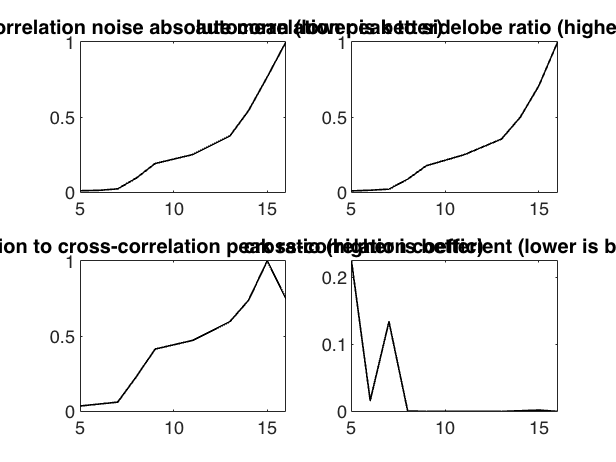


figure('DefaultAxesFontSize',18);
subplot(2,2,1);
plot(degs, ccnoise_list, "k", "LineWidth",1.5); title("cross-correlation noise absolute mean (lower is better)");
subplot(2,2,2);
plot(degs, psr_list, "k", "LineWidth",1.5); title("autocorrelation peak to sidelobe ratio (higher is better)");
subplot(2,2,3);
plot(degs, acr_list, "k", "LineWidth",1.5); title("autocorrelation to cross-correlation peak ratio (higher is better)");
subplot(2,2,4);
plot(degs, ccoef_list, "k", "LineWidth",1.5); title("cross-correlation coefficient (lower is better)");

rx = zeros(1,numel(anchor1));
% an dieser stelle werden die signale von den verschiedenen ankern gemixt.
% alle haben unterschiedliche laufzeiten
delay1 = 50; % delay in seconds
idx = (delay1 + 1):(delay1 + numel(anchor1));


rx(idx) = rx(idx)' + anchor1;
delay2 = 100; % delay in seconds
idx = (delay2 + 1):(delay2 + numel(anchor2));
pos1 = xcorr(rx,anchor1);
pos2 = xcorr(rx,anchor1);

subbplot(1,1,1);
plot(pos1, "r");
hold on;
plot(pos2, "b")
hold off;



% n = size(anchor1, 2);
% time = linspace(0, n / fs * 1000, n);
% subplot(2,1,1); plot(time, anchor1 / max(abs(anchor1)), "g", "LineWidth",1.5); title("Anchor 1");
% xlabel("time [ms]"); ylabel("amplitude");
% subplot(2,1,2); plot(time, anchor2 / max(abs(anchor2)), "r", "LineWidth",1.5); title("Anchor 2")
% xlabel("time [ms]"); ylabel("amplitude");
% 
% rx = zeros(1,2*numel(anchor1));
% delay1 = 10e-3; % delay in seconds
% idx = (floor(delay1*fs) + 1):(floor(delay1*fs) + numel(anchor1) );
% rx(idx) = rx(idx) + anchor1;
% delay2 = 20e-3; % delay in seconds
% idx = (floor(delay2*fs) + 1):(floor(delay2*fs) + numel(anchor2));
% rx(idx) = rx(idx) + anchor2;
% 
% [cr1,tau1] = xcorr(anchor2,anchor1);
% [ar1,atau1] = xcorr(anchor1,anchor1);
% [ar2,atau2] = xcorr(anchor2,anchor2);
% subplot(1, 1, 1);
% plot(tau1 / fs * 1000, abs(cr1), "k", "LineWidth",1.5);
% subplot(1, 2, 1);
% plot(atau1 / fs * 1000, abs(ar1) / max(ar1), "k", "LineWidth",1.5);
% subplot(1, 2, 2);
% plot(atau2 / fs * 1000, abs(ar2) / max(ar2), "k", "LineWidth",1.5);
% 
% % correlation quality measures
% 
% % peak to sidelobe ratio
% 
% psr1 = (max(abs(ar1)) - mean(abs(ar1))) / std(abs(ar1))
% psr2 = (max(abs(ar2)) - mean(abs(ar2))) / std(abs(ar2))
% 
% % autocorrelation peak to cross-correlation ratio
% 
% acr1 = max(abs(ar1)) / mean(abs(cr1))